clear;close;clc;

Q1=12.1:-0.1:11.8;
Q2=13.2:-0.1:13.0;

K1=size(Q1,2);
K2=size(Q2,2);
K=K1+K2

K = 7

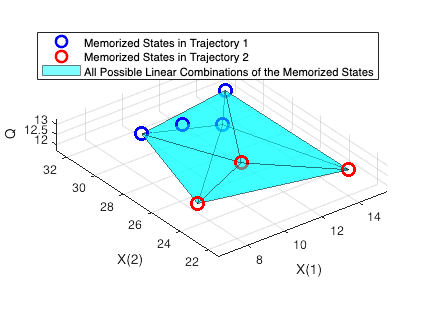

X1=linspace(10,15,K1);
X2=linspace(7,14,K2);

Y1=linspace(30,32,K1);
Y2=linspace(22,25,K2);

X1=X1(randperm(K1));
X2=X2(randperm(K2));
Y1=Y1(randperm(K1));
Y2=Y2(randperm(K2));

X=[X1 X2]';
Y=[Y1 Y2]';
Q=[Q1 Q2]';
data=[X Y Q];

% [X,Y,Q]=meshgrid(X,Y,Q);
% X=X(:);
% Y=Y(:);
% Q=Q(:);
K=convhull(X,Y,Q,'Simplify',true);

figure
plot3(X1,Y1,Q1,'bo', ...
    MarkerSize=10,LineWidth=2,DisplayName="Memorized States in Trajectory 1")
hold on
plot3(X2,Y2,Q2,'ro', ...
    MarkerSize=10,LineWidth=2,DisplayName="Memorized States in Trajectory 2")
trisurf(K,X,Y,Q, 'EdgeAlpha', 0.5,'FaceColor','Cyan','FaceAlpha',0.5, ...
    DisplayName="All Possible Linear Combinations of the Memorized States")
axis equal padded
grid on
xlabel("X(1)")
ylabel("X(2)")
zlabel("Q")
legend(Location="northeast")

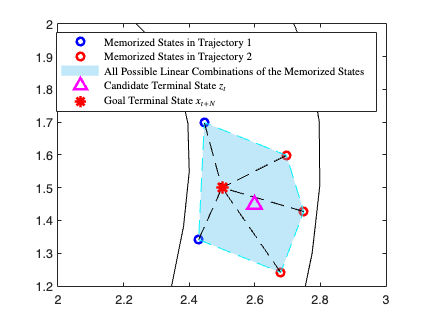

load("track.mat")
figure
plot(leftBoundary(1,:),leftBoundary(2,:),'k-',HandleVisibility='off')
hold on
plot(rightBoundary(1,:),rightBoundary(2,:),'k-',HandleVisibility='off')
axis equal
axis([2 3 1.2 2])

traj=centerline(:, centerline(1,:)>2.4 & centerline(1,:)<2.7 & centerline(2,:)>1.3 & centerline(2,:)<1.8);

traj1=traj+[-0.15, 0]';
traj2=traj+[0.1, -0.1]';

traj1=[traj1(:,1) traj1(:,3)];
traj2=[traj2(:,1) traj2(:,2)+[0.05 0]' traj2(:,3)];

plot(traj1(1,:),traj1(2,:),'bo',LineWidth=2,DisplayName="Memorized States in Trajectory 1")
plot(traj2(1,:),traj2(2,:),'ro',LineWidth=2,DisplayName="Memorized States in Trajectory 2")

x=[traj1(1,:) traj2(1,:)]';
y=[traj1(2,:) traj2(2,:)]';
k=convhull(x,y);
plot(x(k),y(k),'c--',HandleVisibility='off')
h = polyshape([x(k) y(k)]);
plot(h,"EdgeAlpha",0,DisplayName="All Possible Linear Combinations of the Memorized States")
legend(Interpreter="latex")

z=[2.6,1.45]';
xn=[2.5 1.5]';
connectLines=[];
for i=1:size(x)
    connectLines=[connectLines [x(i) y(i)]' xn [NaN NaN]'];
end
plot(connectLines(1,:),connectLines(2,:),'k--',HandleVisibility='off')
plot(z(1),z(2),'m^',LineWidth=2,MarkerSize=10,DisplayName="Candidate Terminal State $z_t$")
plot(xn(1),xn(2),'r*',LineWidth=2,MarkerSize=10,DisplayName="Goal Terminal State $x_{t+N}$")

% lin_combinations = linear_combinations(data);

% X=[];
% Y=[];
% Q=[];
% for i=1:size(lin_combinations,1)
%     data=lin_combinations{i,2};
%     X=[X data(1)];
%     Y=[Y data(2)];
%     Q=[Q data(3)];
% end
% 
% save("lambdas","lin_combinations","X","Y","Q")

% load("lambdas.mat");

% plot3(X,Y,Q,'g.', ...
%     MarkerSize=10,DisplayName="Linear Combinations of Memorized States")


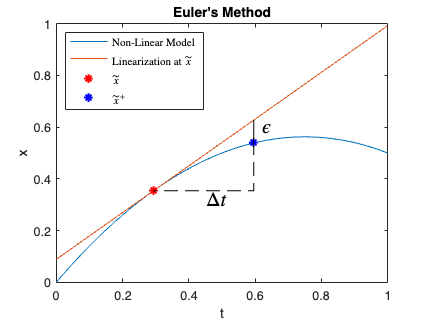

a=-1;
b=1.5;
ql=@(x)a.*x.^2+b.*x;

x=linspace(0,1,100);
y=ql(x);

indx=30;
dydx=diff(y)./diff(x);


x0=x(indx);
y0=y(indx);
dydx0=dydx(indx);

ll=@(x)(x-x0).*dydx0+y0;

figure
plot(x,y,DisplayName="Non-Linear Model")
hold on
plot(x,ll(x),DisplayName="Linearization at $\tilde{x}$")
xlabel("t")
ylabel("x")
title("Euler's Method")

plot(x0,y0,'r*',MarkerSize=7,LineWidth=1.5,DisplayName="$\tilde{x}$")

indx=indx+30;
x1=x(indx);
y1=ll(x1);
yy1=y(indx);


plot(x1,yy1,'b*',MarkerSize=7,LineWidth=1.5,DisplayName="$\tilde{x}^+$")
plot([x1 x1],[yy1 y1],'k--',HandleVisibility='off')
plot([x1 x1 x0],[y1 y0 y0],'k--',HandleVisibility='off')
text(x1+0.02,(yy1+y1)/2+0.02,"$\epsilon$",Interpreter="latex",FontSize=16)
text((x1+x0)/2,y0-0.03,"$\Delta t$",Interpreter="latex",FontSize=16)

legend(Location="northwest",Interpreter="latex")

a=-1;
b=0.15;
c=0.15;
d=1;

X=-linspace(-0.8,-0.2,6);
Y=a.*X.^3+b.*X.^2+c.*X+d;

epsilon=0.05;
epsilonX=rand(1,6).*epsilon;
epsilonY=rand(1,6).*epsilon;

Xe=X+epsilonX;
Ye=Y+epsilonY;

dX=diff(Xe);
dY=diff(Ye);

l=size(dX,2)

l = 5

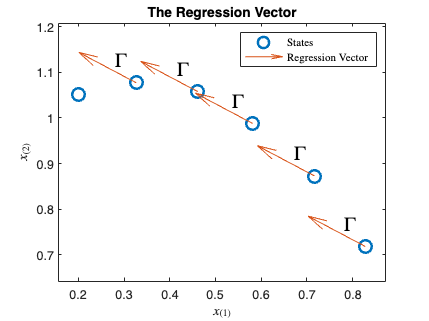


dX=sum(dX)/l;
dY=sum(dY)/l;

figure
plot(Xe,Ye,'o',MarkerSize=10,LineWidth=2, DisplayName="States")
hold on
axis equal padded
% axis([0 1 0 1])
xlabel("$x_{(1)}$",Interpreter="latex")
ylabel("$x_{(2)}$",Interpreter="latex")
title("The Regression Vector")
legend(Location="northeast",Interpreter="latex")

quiver(Xe(1:l), Ye(1:l), ...
    ones(1,l)*dX, ones(1,l)*dY,AutoScale="off",DisplayName="Regression Vector")

text(Xe(1:l)-0.05,Ye(1:l)+0.05,"$\Gamma$",Interpreter="latex",FontSize=16)

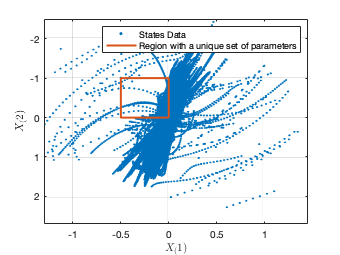

xlim=[-1.3 1.45];
ylim=[-2.7 2.5];

figure 
im=imread("LPV.png");
h = image(xlim,-ylim,im); 
uistack(h,'bottom')
hold on
xlabel("$X_(1)$",Interpreter="latex")
ylabel("$X_(2)$",Interpreter="latex")
plot(0,0,'.','DisplayName',"States Data")

plot([0 0 -0.5 -0.5 0],[0 -1 -1 0 0], ...
    LineWidth=2, ...
    DisplayName="Region with a unique set of parameters")
legend